t=0:0.01:3;
v_ref=1;
analog=v_ref/2*sin(2*pi*t);
N=[2 4 12];
n1=round(analog./v_ref *2.^N(1)) * v_ref/2.^N(1);
n2=round(analog./v_ref *2.^N(2))* v_ref/2.^N(2);
n3=round(analog./v_ref *2.^N(3))* v_ref/2.^N(3);

figure;
ax = gca

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


grid;
ax.GridLineWidth = 3;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


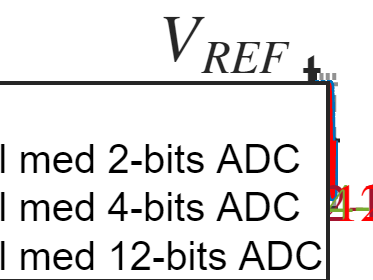

ax.LineWidth = 3;
ax.XAxisLocation="origin";
ax.FontSize=50;
ax.TickLabelInterpreter='latex';
set(ax.YLabel,'rotation',0);
hold on;
plot(t,analog,'LineWidth',7,'Color',[0 0.4470 0.7410]);
plot(t(1:100),n1(1:100),'LineWidth',3,'Color',[0.6350 0.0780 0.1840]);
plot(t(101:200),n2(101:200),'LineWidth',3,'Color',[0.4660 0.6740 0.1880]);
plot(t(201:301),n3(201:301),'LineWidth',3,'Color','r');


text(0.1,-0.55,sprintf('%d-bits: $\\Delta = \\frac{V_{REF}}{%d}$', N(1), 2^N(1)),'Color',[0.6350 0.0780 0.1840],'Fontsize', 40, 'Interpreter', 'latex')
text(1.1,-0.55,sprintf('%d-bits: $\\Delta = \\frac{V_{REF}}{%d}$', N(2), 2^N(2)),'Color',[0.4660 0.6740 0.1880],'Fontsize', 40, 'Interpreter', 'latex')
text(2.1,-0.55,sprintf('%d-bits: $\\Delta = \\frac{V_{REF}}{%d}$', N(3), 2^N(3)),'Color','r','Fontsize', 40, 'Interpreter', 'latex')


xlabel("t"); xlim([0 3.6])
xticks([1 2 3]);
xticklabels({""});

ylabel("[V]"); ylim([-0.6 0.6])
yticks([-0.5 0 0.5]);
yticklabels({"$-\frac{V_{REF}}{2}$","0","$\frac{V_{REF}}{2}$"});

set(get(gca,'ylabel'),'rotation',0);

legend("Analogt signal","Samplet signal med "+N(1)+"-bits ADC","Samplet signal med "+N(2)+"-bits ADC","Samplet signal med "+N(3)+"-bits ADC",'FontSize',30);